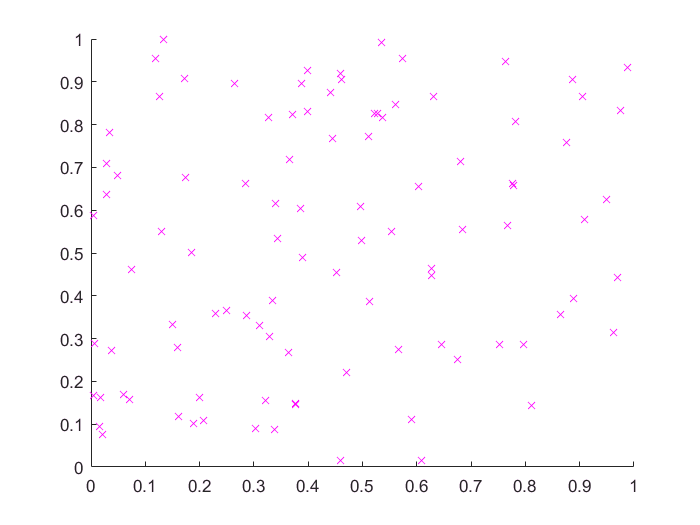

clearvars
close all
%Initialization
x_init.coord = [0.1,0.1];
x_init.cost = 0;
x_init.ind = 1;
x_init.parent = 0; %"n"th place of parent node in Vertex set
x_goal.coord = [0.9,0,9]; %Final Point (Not fully defined yet)
Tree = graph;
Tree = addnode(Tree, 1)
Vertex(1) = x_init;    %Initializing Vertex; Edge variable not needed since it is defined within the field
num_iter = 100; %Set number of iteration
EPS = .05; %Maximum edge length
figure;
axis([0 1 0 1])
hold on

for x = 1:num_iter
    x_rand.coord = [rand(),rand()];
    %x_nearest = Nearest(Vertex,x_rand)
    plot(x_rand.coord(1),x_rand.coord(2),'x','color','m')
    for y = 1:length(Vertex)
        if CollisionFree(Vertex(y).coord, x_goal,coord,obstacle) == 1
            break
        end
    end
    % Pick the closest node from existing list to branch
    dist_list = [];
    for z = 1:length(Vertex)
        n = Vertex(z);
        dist = distance(n.coord, q_rand.coord);
        dist_list = [dist_list dist];
    end
    [val,index] = min(dist_list);
    x_near = Vertex(index);
    x_new.coord = steer(x_rand, x_near.coord, EPS)
    
    if CollisionFree(x_rand, x_near.coord, obstacle)
        line([x_near.coord(1), x_new.coord(1)], [x_near.coord(2), x_new.coord(2)], 'Color', 'b', 'LineWidth', 1);
        drawnow
        hold on
        Tree = add
        x_new.cost = dist(x_new.coord, x_near.coord) + x_near.cost;
end

function y = Nearest(V,x) % Nearest(V,E,x): returns vertex that is cloest to x.
    min_dist = intmax;
    y(1) = 1;
    y(2) = V(1); 
    a = 2
    while a <= length(V)
            
    end
end